## A minimalistic Echo State Networks demo with Mackey-Glass (delay 17) data in "plain" scientific Python 

### by Mantas Lukoševičius 2012. Original Source: [http://minds.jacobs-university.de/mantas](http://minds.jacobs-university.de/mantas)

## Modified and adapted for Sine Wave Synthesis using a Small-World Architecture 

### by Jack Kenney 2018, translated and optimized in MATLAB 2019. BINDS Lab, CICS, UMass Amherst

% data parameters
global in_size
global out_size
in_size = 2;             % input vector size
out_size = 1;            % output vector size
% hyper parameters
hyper.res_size = 350;          % size of reservoir
hyper.leak = 0.15;             % leaking rate for integrator neurons
hyper.noise = 1e-9;            % magintude of noise term
hyper.aux = 1;                 % a_0 for x^0 doing a linear fit, bias term
hyper.feedback_scaling = 1.5;  % output feedback scaling
hyper.train_test_ratio = 0.8;
hyper.init_ratio = 0.1; 

load('data/waves_20_100')
% normalize to prevent neuron saturation
input_data = normalize(input_data,2);

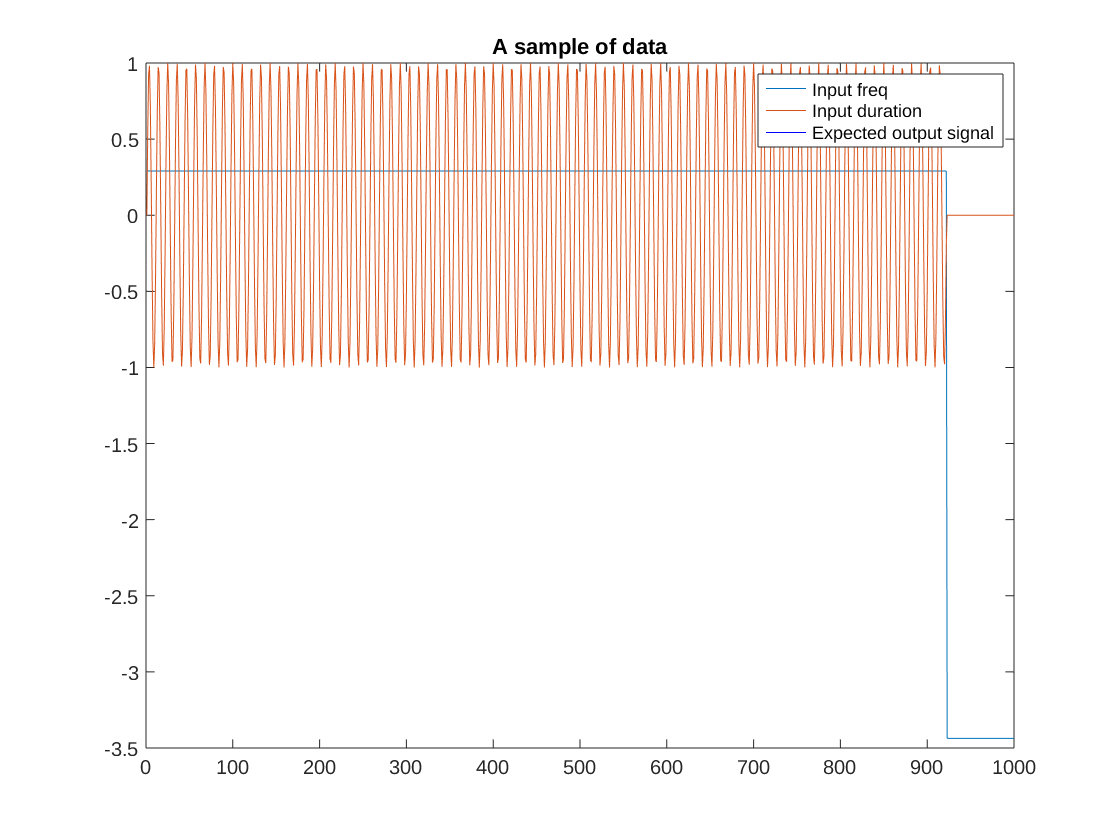

% plot some of the data
figure(1)
plot(input_data(1,:,1))
hold on
plot(input_data(1,:,2))
plot(output_data(1,:))
title('A sample of data')
legend('Input freq', 'Input duration', 'Expected output signal')

rng(42)

disp('Building small world...');

Building small world...


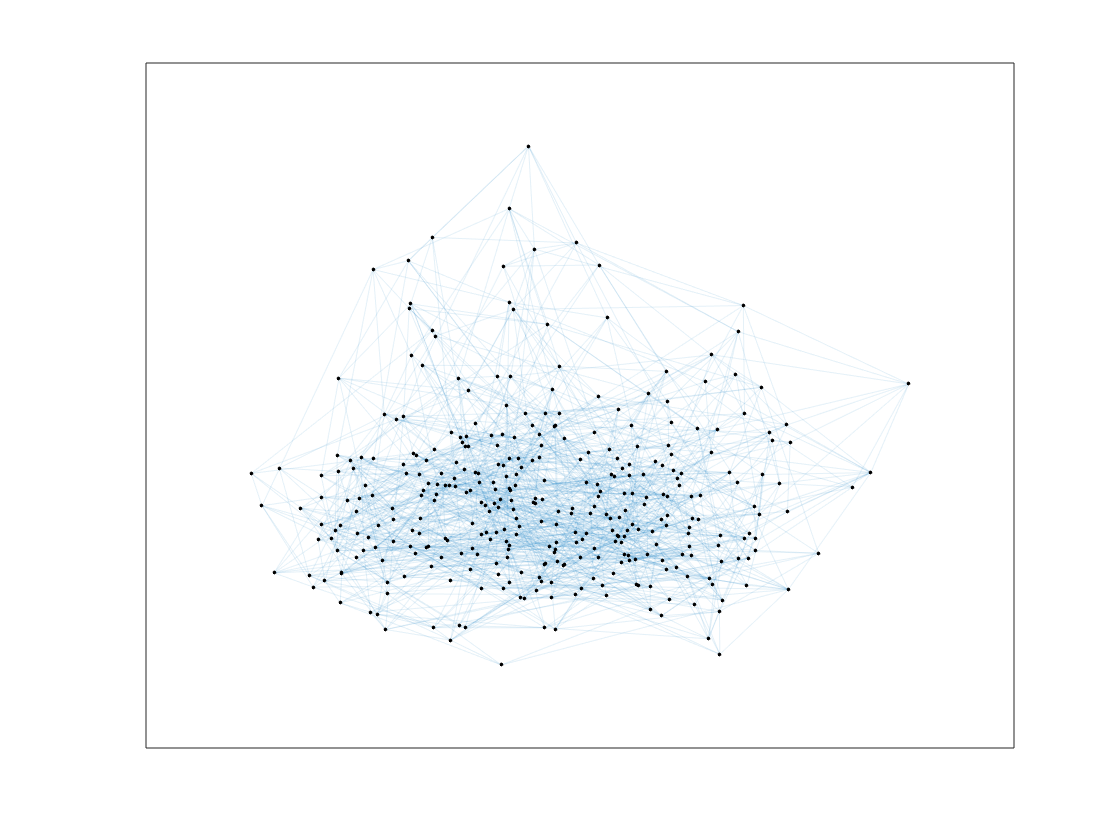

G = WattsStrogatz(res_size, 4, 0.7);
figure(2)
plot(G,'NodeColor','k','EdgeAlpha',0.1);

weights.Win = rand([res_size, 1 + in_size]) * 2 - 1;
weights.W = adjacency(G);
for i = 1:size(weights.W,1)
    parfor j = 1:size(weights.W,2)
        % assign rand to edge (each edge is init_len to 1)
        weights.W(i,j) = weights.W(i,j) * (rand()*2-1);
    end
end

Error: Unable to classify the variable 'weights' in the body of the parfor-loop. For more information, see Parallel for Loops in MATLAB, "Solve Variable Classification Issues in parfor-Loops".


% initialize random weight matrices
weights.Wfb = rand([res_size, out_size]) * 2 - 1;
disp('done.')

disp('Printing graph...')

Printing graph...


savefig("last_internal_weight_graph")
disp('done.')

done.


% DIVIDE DATA

% TRAIN
disp('Beginning training...');

Beginning training...


% allocated memory for the design (collected states) matrix
X = zeros([1 + in_size + res_size, init_len]);
% set the corresponding target matrix directly
Yt = output_data(init_len+1:train_len + 1);

Unrecognized function or variable 'train_len'.

% run the reservoir with the data and collect X
x = zeros([res_size, 1])

% for sample = 1:size(input_data,1)
%     for t = 1:sample_lengths(sample)
%     noise = noise_mag*rand()*2-1; % small noise term referenced on p.26 of ESN Tutorial
%     u = input_data(sample,t,:);  % Regularize inputs
%     y = output_data(sample,t);
% %     kept = (1 - leak) * x;
%     x = prop(weights, hyper, u, x, y, noise);
%     if t >= init_len
% %         stacked = ;
% %         reshaped = stacked(:, 1)
% %         reshaped = reshape(reshaped, [1 + in_size + res_size])
%         X(:, t - init_len) = [aux; u; x];
%     end
%     end
% end

% % batch train the output weights
% reg = 1e-8  % regularization coefficient
% X_T = X.T
% Wout = np.dot(np.dot(Yt, X_T),
%               linalg.inv(np.dot(X, X_T) + \
%               reg * np.eye(1 + in_size + res_size)))
% % optionally use the pseudoinverse - slower
% % Wout = np.dot( Yt, linalg.pinv(X) )
% print('done.')
% % TEST
% print('Beginning testing...', end='')
% Y = np.zeros((out_size, test_len - 1))
% u = input_data[train_len]  % Regularize inputs
% y = [[0] * out_size]
% % noise only required in training
% noise = 0
% % run test
% for t in range(test_len - 1):
%     x = prop(u, x, y)
%     y = np.dot(Wout, np.vstack((aux, u, x)))
%     Y[:, t] = y
%     u = input_data[train_len + t + 1]  % Regularize inputs
% print('done.')
% % Compute MSE for the first errorLen time steps
% errorLen = 500
% end = train_len + errorLen + 1
% mse = sum(np.square(output_data[train_len + 1:end] - Y[0, 0:errorLen])) / errorLen
% print('MSE = ' + str(mse))
% rmse = np.sqrt(mse)
% nrmse = rmse / (max(output_data) - min(output_data))  % rmse / (ymax-ymin)
% print('NRMSE = ' + str(nrmse))
% % plot some signals
% figure(11).clear()
% plot(output_data[train_len + 1:train_len + test_len + 1], 'g')
% plot(Y.T, 'b')
% title('Target and generated signals')
% legend(['Target signal', 'Free-running predicted signal'])
% 
% figure(12).clear()
% plot(X[0:res_size, 0:200].T)
% title('Some reservoir activations')
% 
% figure(13).clear()
% bar(range(1 + in_size + res_size), Wout.T.reshape(1 + in_size + res_size,))
% title('Output weights $\mathbf{W}^{out}$')


function out = prop(weights, hyper, u, x, y, noise)
    % This is a function used to propagate input data through the reservoir.
    kept = (1 - hyper.leak) * x;
    vector = weights.Win*[hyper.aux; u] + weights.W*x + ...
             hyper.feedback_scaling * weights.Wfb*y;
    % TANH activated
    injected = hyper.leak * (tanh(vector) + noise);
    out = kept + injected;
end

function data = divide_data(input_data, output_data, sample_lengths, hyper)
    init_end_sample = hyper.init_ratio * size(sample_lengths,1)
    in_init = input_data(1:init_end_sample, :)
    in_init = reshape(in_init, [numel(in_init),in_size])
%     in_train = 
%     in_test = 
    out_init = output_data(1:init_end_sample, :)
    out_init = reshape(out_init, [numel(out_init),out_size])
%     out_train =
%     out_test = 
end